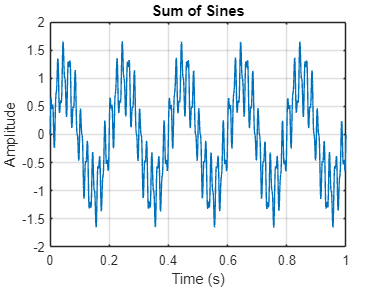

% Parameters for the sum of sines
Fs = 1000;  % Sampling frequency
T = 1;      % Duration in seconds
t = linspace(0, T, Fs * T);  % Time vector

% Frequencies and amplitudes of the sine waves
frequencies = [5, 50, 120];  % Frequencies in Hz
amplitudes = [1, 0.5, 0.2];  % Amplitudes

% Generate the sum of sines
signal = zeros(size(t));
for i = 1:length(frequencies)
    signal = signal + amplitudes(i) * sin(2 * pi * frequencies(i) * t);
end

% Plot the signal
figure;
plot(t, signal);
title('Sum of Sines');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


% Save the signal to a file for further use
%writematrix(signal, 'sum_of_sines.txt');

% Create the mxn matrix with shifted rows
m = 100;  % Number of rows
n = length(signal);  % Number of columns
shifted_matrix = zeros(m, n);

for i = 1:m
    shifted_matrix(i, :) = circshift(signal, i-1);
end

data = shifted_matrix'

data =          0   -0.0000   -0.3231   -0.5566   -0.6528   -0.6256   -0.5384   -0.4662   -0.4539   -0.4932   -0.5300   -0.4984   -0.3632   -0.1450    0.0836    0.2319    0.2351    0.0868   -0.1588   -0.4150   -0.6068   -0.7065   -0.7429   -0.7784   -0.8691   -1.0275   -1.2114   -1.3435   -1.3525   -1.2128   -0.9616   -0.6837   -0.4712   -0.3807   -0.4088   -0.5005   -0.5833   -0.6101   -0.5856   -0.5623   -0.6092   -0.7695   -1.0304   -1.3240   -1.5569   -1.6553   -1.5999   -1.4336   -1.2373   -1.0869
    0.3231         0   -0.0000   -0.3231   -0.5566   -0.6528   -0.6256   -0.5384   -0.4662   -0.4539   -0.4932   -0.5300   -0.4984   -0.3632   -0.1450    0.0836    0.2319    0.2351    0.0868   -0.1588   -0.4150   -0.6068   -0.7065   -0.7429   -0.7784   -0.8691   -1.0275   -1.2114   -1.3435   -1.3525   -1.2128   -0.9616   -0.6837   -0.4712   -0.3807   -0.4088   -0.5005   -0.5833   -0.6101   -0.5856   -0.5623   -0.6092   -0.7695   -1.0304   -1.3240   -1.5569   -1.6553   -1.5999   -1.4336  

%disp('Sum of sines signal generated and saved to ''sum_of_sines.txt''.');
data = data %+ randn(10000, 100);

data =          0   -0.0000   -0.3231   -0.5566   -0.6528   -0.6256   -0.5384   -0.4662   -0.4539   -0.4932   -0.5300   -0.4984   -0.3632   -0.1450    0.0836    0.2319    0.2351    0.0868   -0.1588   -0.4150   -0.6068   -0.7065   -0.7429   -0.7784   -0.8691   -1.0275   -1.2114   -1.3435   -1.3525   -1.2128   -0.9616   -0.6837   -0.4712   -0.3807   -0.4088   -0.5005   -0.5833   -0.6101   -0.5856   -0.5623   -0.6092   -0.7695   -1.0304   -1.3240   -1.5569   -1.6553   -1.5999   -1.4336   -1.2373   -1.0869
    0.3231         0   -0.0000   -0.3231   -0.5566   -0.6528   -0.6256   -0.5384   -0.4662   -0.4539   -0.4932   -0.5300   -0.4984   -0.3632   -0.1450    0.0836    0.2319    0.2351    0.0868   -0.1588   -0.4150   -0.6068   -0.7065   -0.7429   -0.7784   -0.8691   -1.0275   -1.2114   -1.3435   -1.3525   -1.2128   -0.9616   -0.6837   -0.4712   -0.3807   -0.4088   -0.5005   -0.5833   -0.6101   -0.5856   -0.5623   -0.6092   -0.7695   -1.0304   -1.3240   -1.5569   -1.6553   -1.5999   -1.4336  

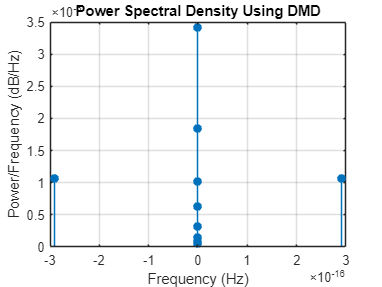


% Sample data (replace with your actual data)
%data = randn(1000, 100); % Example data

% Perform DMD (using a simple DMD implementation)
[U, S, V] = svd(data, 'econ');
r = 10; % Number of modes
U_r = U(:, 1:r);
S_r = S(1:r, 1:r);
V_r = V(:, 1:r);
A_tilde = U_r' * data * V_r / S_r;
[W, D] = eig(A_tilde);
Phi = data * V_r / S_r * W;

% Compute DMD frequencies
dt = 1; % Time step (replace with your actual time step)
lambda = diag(D);
omega = log(lambda) / dt;
frequencies = imag(omega) / (2 * pi);

% Compute the PSD
amplitudes = abs(Phi);
psd = (amplitudes.^2) / length(data);

% Plot the PSD
figure;
stem(frequencies, psd(1,:), 'filled');
grid on;
title('Power Spectral Density Using DMD');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');